
clearvars;

% =========================================================================
% DEFINE LITERALS
% =========================================================================
    

% medium parameters
c0              = 1500;     % sound speed [m/s]
rho0            = 1000;     % density [kg/m^3]
u               = 0.04;
cbrain          = 1560;     % speed of sound [m/s]
rhobrain        = 1040; 
cskullcortical  = 2800;     % speed of sound [m/s]
rhoskullcortical= 1850; 

alphabrain = 1.2;
alphatrab = 32;
alphacort = 16;
alpha0 = 0;


% source parameters
source_f0       = 500000;   % source frequency [Hz]
source_roc      = 15e-3;    % bowl radius of curvature [m]
source_diameter = 20e-3;    % bowl aperture diameter [m]
source_mag      = rho0*c0*u;% source pressure [Pa]
offset          = source_roc - sqrt((source_roc^2)-(source_diameter/2)^2);

% grid parameters
%axial_size      = 64e-3;    % total grid size in the axial dimension [m]
%lateral_size    = 40e-3;   % total grid size in the lateral dimension [m]
axial_size      = 60e-3;    % total grid size in the axial dimension [m]
lateral_size    = 25e-3;
% computational parameters
ppw             = 11;        % number of points per wavelength
t_end           = 120e-6;    % total compute time [s] (this must be long enough to reach steady state)
record_periods  = 3;        % number of periods to record
cfl             = 0.05;     % CFL number

% =========================================================================
% RUN SIMULATION
% =========================================================================

% --------------------
% GRID
% --------------------

% calculate the grid spacing based on the PPW and F0
dx = c0 / (ppw * source_f0);   % [m]
%dx =10e-04
%dx = 0.00027
source_x_offset = round(offset/dx); %grid points for offset of source 

% compute the size of the grid
Nx = roundEven(axial_size / dx) 

Nx = 220

%+ source_x_offset;
Ny = roundEven(lateral_size / dx);

% create the computational grid
kgrid = kWaveGrid(Nx, dx, Ny, dx);

% compute points per temporal period
PPP = round(ppw / cfl);

% compute corresponding time spacing
dt = 1 / (PPP * source_f0);

% create the time array using an integer number of points per period
Nt = round(t_end / dt);
kgrid.setTime(Nt, dt);

% calculate the actual CFL and PPW
disp(['PPW = ' num2str(c0 / (dx * source_f0))]);

PPW = 11


disp(['CFL = ' num2str(c0 * dt / dx)]);

CFL = 0.05



% --------------------
% SOURCE
% --------------------

% create time varying source
source_sig = createCWSignals(kgrid.t_array, source_f0, source_mag, 0);

%create empty kWaveArray
karray = kWaveArray('Axisymmetric', true, 'BLITolerance', 0.01, 'UpsamplingRate', 10);

% set bowl position and orientation
arc_pos = [kgrid.x_vec(1), 0];
%arc_pos = [kgrid.x_vec(1) + source_x_offset * kgrid.dx, 0];
focus_pos = [kgrid.x_vec(end), 0];

% 
% %create empty kWaveArray
% karray = kWaveArray('Axisymmetric', true, 'BLITolerance', 0.01);
% source_diam     = 0.02; 
% %add line shaped element
% karray.addLineElement([kgrid.x_vec(1), -source_diam/2], [kgrid.x_vec(1), source_diam/2]);


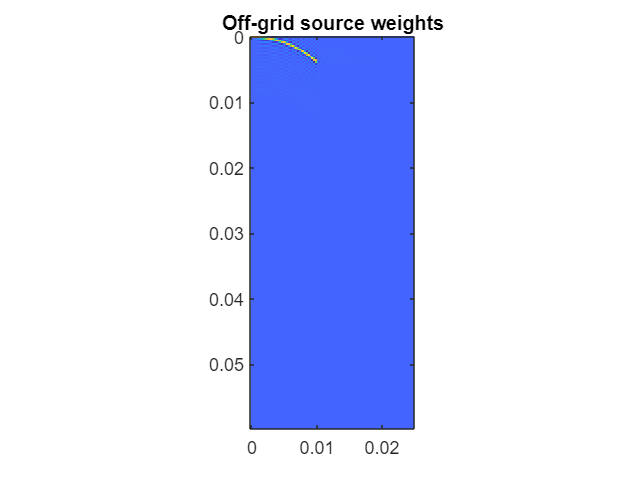

% % % add arc shaped element
karray.addArcElement(arc_pos, source_roc, source_diameter, focus_pos);

% assign binary mask
source.p_mask = karray.getArrayBinaryMask(kgrid);

% assign source signals
source.p = karray.getDistributedSourceSignal(kgrid, source_sig);

% plot grid weights
grid_weights = karray.getArrayGridWeights(kgrid);
figure;
imagesc(kgrid.y_vec - kgrid.y_vec(1), kgrid.x_vec - kgrid.x_vec(1), grid_weights);
axis image;
title('Off-grid source weights');

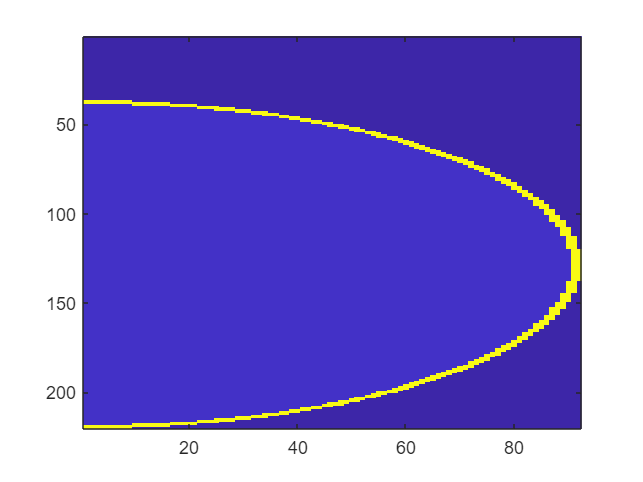


% 
% --------------------
% MEDIUM
% --------------------

nsphere = Ny;
spherestart = 36;
Psphere = [randi(1,nsphere,1); zeros(nsphere, 1)];
[Xsphere, Ysphere] = meshgrid(1:nsphere, flip(1:nsphere));
rsphere = round(sqrt(Xsphere.^2 + Ysphere.^2));
Asphere = reshape(Psphere(rsphere(:)), nsphere, nsphere);
Bsphere = flip(Asphere);
fillmatrix = (Nx-(length(Asphere)*2))-spherestart;
SC = [zeros(spherestart,Ny);Asphere;Bsphere;zeros(fillmatrix,Ny)];

nsphere1 = Ny-2;
spherestart1 = 38;
Psphere1 = [randi(1,nsphere1,1); zeros(nsphere1, 1)];
[Xsphere, Ysphere] = meshgrid(1:nsphere1, flip(1:nsphere1));
rsphere = round(sqrt(Xsphere.^2 + Ysphere.^2));
Csphere = reshape(Psphere1(rsphere(:)), nsphere1, nsphere1);
Dsphere = flip(Csphere);
fillmatrix1 = (Nx-(length(Csphere)*2))-spherestart1;
SC1 = [zeros(spherestart1,nsphere1);Csphere;Dsphere;zeros(fillmatrix1,nsphere1)];
SC1 = [SC1,zeros(Nx,2)];

SCO = SC-SC1;
SCO(SCO==1)=2;
SCO(SCO==0)=1;
SCO(SCO==2)=0;


% define the medium properties
medium.sound_speed = cbrain*SC; % [m/s]
medium.sound_speed(medium.sound_speed == 0) = c0; % [m/s]
medium.sound_speed = medium.sound_speed.*SCO;
medium.sound_speed(medium.sound_speed == 0) = cskullcortical;
imagesc(medium.sound_speed)


medium.density = rhobrain*SC; % [kg/m^3]
medium.density(medium.density == 0) = rho0; % [kg/m^3]
medium.density = medium.density.*SCO; 
medium.density(medium.density == 0) = rhoskullcortical;

diameterofsphere = length(Asphere)*2*dx*10^3 % [m]

diameterofsphere = 50.1818

locationofspherestart = spherestart*dx*10^3

locationofspherestart = 9.8182

locationofsphereend = (diameterofsphere)+locationofspherestart

locationofsphereend = 60

centreofsphere = locationofspherestart + (0.5*diameterofsphere)

centreofsphere = 34.9091

diameterofsphere1 = length(Csphere)*2*dx*10^3 % [m]

diameterofsphere1 = 49.0909

locationofspherestart1 = spherestart1*dx*10^3

locationofspherestart1 = 10.3636

locationofsphereend1 = (diameterofsphere1)+locationofspherestart1

locationofsphereend1 = 59.4545

centreofsphere1 = locationofspherestart1 + (0.5*diameterofsphere1)

centreofsphere1 = 34.9091


% 
% medium.alpha_power = 2;
% medium.alpha_coeff = medium.sound_speed;
% medium.alpha_coeff(medium.alpha_coeff == c0) = alpha0;
% medium.alpha_coeff(medium.alpha_coeff == cskullcortical) = alphacort;
% medium.alpha_coeff(medium.alpha_coeff == cbrain) = alphabrain;



% medium.alpha_coeff = SC*alphabrain*4;
% imagesc(medium.alpha_coeff)
% medium.alpha_coeff(medium.alpha_coeff == 0) = alpha0; 
% imagesc(medium.alpha_coeff)
% medium.alpha_coeff = medium.alpha_coeff.*SCO;
% imagesc(medium.alpha_coeff)
% medium.alpha_coeff(medium.alpha_coeff == 0) = alphacort*4;
%medium.alpha_coeff = medium.alpha_coeff*4;
% imagesc(medium.alpha_coeff)
% 
% medium.alpha_coeff = SC*alphabrain*4;
% imagesc(medium.alpha_coeff)
% medium.alpha_coeff(medium.alpha_coeff == 0) = alpha0; 
% imagesc(medium.alpha_coeff)
% medium.alpha_coeff = medium.alpha_coeff.*SCO;
% imagesc(medium.alpha_coeff)
% medium.alpha_coeff(medium.alpha_coeff == 0) = alphacort*4;
% %medium.alpha_coeff = medium.alpha_coeff*4;
%imagesc(medium.alpha_coeff)

% medskull = zeros(Nx,Ny);
% medskull(120:146,1:140) = 1;
% imagesc(medskull);
% % medskull(30:36,1:35) = 1;
% % imagesc(medskull);
% axis equal
% % 
% % % 
% % 
% 
% medium.sound_speed= cskullcortical*medskull;
% medium.sound_speed(medium.sound_speed == 0) = c0;
% 
% medium.density = rhoskullcortical*medskull;
% medium.density(medium.density == 0) = rho0;
% 
% medium.alpha_power = 2;
% 
% medium.alpha_coeff = alphacort*medskull;
% medium.alpha_coeff(medium.alpha_coeff == 0) = alpha0;
% 
% % medium.sound_speed= c0;
% % 
% % medium.density =  rho0;
% % 
% % medium.alpha_power = 2;
% % 
% % medium.alpha_coeff = 4;

% cuboidstart = dx*120*1e3
% cuboidend = dx* 146*1e3
% cuboidwidth = dx*26*1e3
% cuboiddiam = dx*140*1e3

Running k-Wave simulation...
  start time: 02-May-2022 17:17:16
  reference sound speed: 2800m/s
  dt: 9.0909ns, t_end: 119.9909us, time steps: 13200
  input grid size: 220 by 92 grid points (60 by 25.0909mm)
  maximum supported frequency: 2.75MHz
  expanding computational grid...
  computational grid size: 256 by 128 grid points
  casting variables to single type...
  precomputation completed in 9.4343s
  starting time loop...
  estimated simulation time 25min 59.184s...


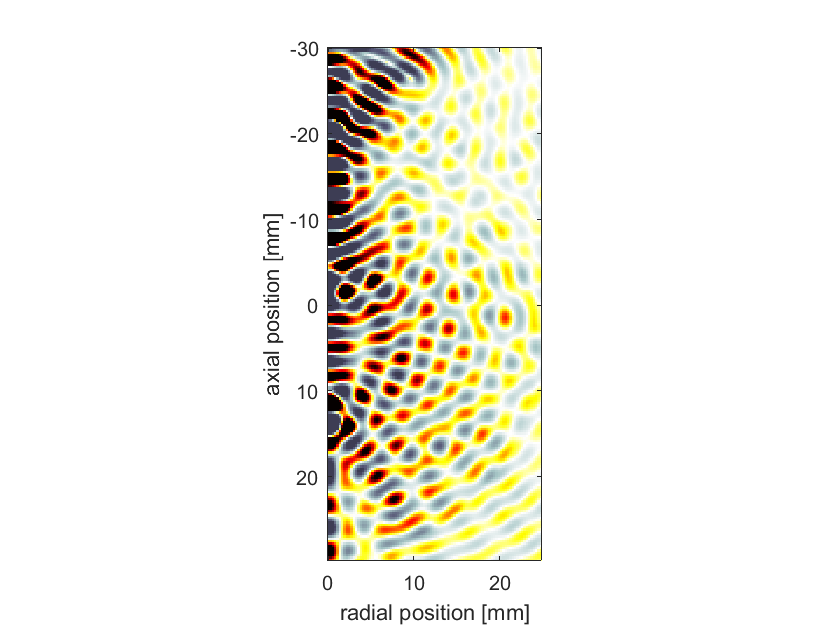

  simulation completed in 24min 7.5237s
  total computation time 24min 19.747s


% --------------------
% SENSOR
% --------------------

% set sensor mask to record central plane, not including the source point
sensor.mask = zeros(Nx, Ny);
sensor.mask(:, :) = 1;

% record the pressure
sensor.record = {'p'};

% --------------------
% SIMULATION
% --------------------

% set input options
input_args = {...
    'PMLSize', 'auto', ...
    'PMLInside', false, ...
    'PlotPML', false, ...
    'DisplayMask', 'off'};

% run code

sensor_data = kspaceFirstOrderAS(kgrid, medium, source, sensor, ...
    input_args{:}, ...
    'DataCast', 'single', ...
    'PlotScale', [-1, 1] * source_mag);


% extract amplitude from the sensor data
amp = extractAmpPhase(sensor_data.p, 1/kgrid.dt, source_f0, ...
    'Dim', 2, 'Window', 'Rectangular', 'FFTPadding', 1);

% sensor_P = reshape(sensor_data.p, kgrid.Nx, kgrid.Ny, length(kgrid.t_array));
% sensor_P_xy = sensor_P(:,kgrid.Ny/2,:);
% sensor_P_xy = reshape(sensor_P_xy, kgrid.Nx,length(kgrid.t_array));
% [freq, amp_spect] = spect(sensor_P_xy, 1/kgrid.dt, 'Dim', 2);
% [f1_value, f1_index] = findClosest(freq, source_f0);
% P = amp_spect(:, f1_index);

% plot(P)

% reshape data
amp = reshape(amp, Nx, Ny);
%- source_x_offset - 1
% extract pressure on axis
amp_on_axis = amp(:, 1);

% define axis vectors for plotting
x_vecc = kgrid.x_vec(source_x_offset + 2:end, :) - kgrid.x_vec(source_x_offset + 1);
y_vec = kgrid.y_vec - kgrid.y_vec(1);


% % =========================================================================
% % ANALYTICAL SOLUTION
% % =========================================================================
% 
% % calculate the wavenumber
% k = 2 * pi * source_f0 ./ c0;
% 
% % define radius and axis
% x_max = (Nx * dx);
% x_ref = 0:x_max/10000:x_max;
% 
% % calculate analytical solution
% p_ref_axial = focusedBowlONeil(source_roc, source_diameter, source_mag / (c0 * rho0), source_f0, c0, rho0, x_ref, []);
% 
% % calculate analytical solution at exactly the same points as k-Wave
% p_ref_axial_kw = focusedBowlONeil(source_roc, source_diameter, source_mag / (c0 * rho0), source_f0, c0, rho0, x_vecc, []);
% 
% % calculate error
% L2_error = 100 * sqrt( sum( (p_ref_axial_kw(:) - amp_on_axis(:)).^2 ) / sum( p_ref_axial_kw(:).^2 ) );
% Linf_error = 100 * max(abs(p_ref_axial_kw(:) - amp_on_axis(:))) / max(p_ref_axial_kw(:));

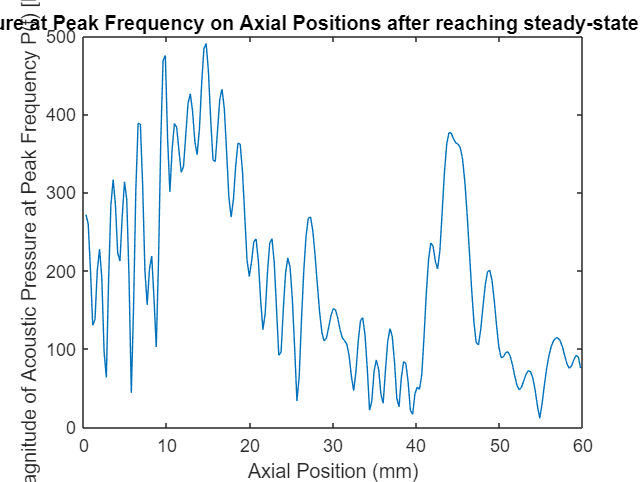

% =========================================================================
% Extracting Pressure and Time Data
% =========================================================================
x_vec = kgrid.x_vec(2:end, :) - kgrid.x_vec(1);

timeperiod= 0:dt:t_end-dt;
periodofwave = 1/source_f0;
cyclelength = periodofwave/dt;
timeindex = Nt-(cyclelength-1);
wavetime = timeperiod(timeindex:Nt);
samplingfrequency = 1/dt;
freqv = (0:cyclelength/2-1)*samplingfrequency/cyclelength;
FFTarray = [];
FFTmag = [];
for i=1:Nx-1
    pressuretime = sensor_data.p(i, 1:Nt);
    cycleextract = pressuretime(timeindex:Nt);
    FFT = fft(cycleextract);

    %symmetric so remove second half
    FFT = FFT(1:(round(cyclelength,0))/2);
    %magnitude of fft
    mFFT = (abs(FFT));
    scaledFFT = mFFT*(2/PPP);
    [FFTpeak, FFTindex] = max(scaledFFT);
    peakfreq = freqv(FFTindex);
    FFTarray = [FFTarray,peakfreq];
    FFTmag = [FFTmag,FFTpeak];
end
% =========================================================================
% VISUALISATION
% =========================================================================

% plot fft 
figure;
plot(x_vec*10^3,FFTmag/10^3)
ylabel('Magnitude of Acoustic Pressure at Peak Frequency P(f) [kPa]')
xlabel('Axial Position (mm)')
title('Acoustic Pressure at Peak Frequency on Axial Positions after reaching steady-state with a bowl piston')




% % =========================================================================
% % ANALYTICAL SOLUTION
% % =========================================================================
% 
% % calculate the wavenumber
% k = 2 * pi * source_f0 ./ c0;
% 
% % define radius and axis
% x_max = (Nx * dx);
% x_ref = 0:x_max/10000:x_max;
% 
% % calculate analytical solution
% p_ref_axial = focusedBowlONeil(source_roc, source_diameter, source_mag / (c0 * rho0), source_f0, c0, rho0, x_ref, []);
% 
% % calculate analytical solution at exactly the same points as k-Wave
% p_ref_axial_kw = focusedBowlONeil(source_roc, source_diameter, source_mag / (c0 * rho0), source_f0, c0, rho0, x_vecc, []);
% 
% % calculate error
% L2_error = 100 * sqrt( sum( (p_ref_axial_kw(:) - amp_on_axis(:)).^2 ) / sum( p_ref_axial_kw(:).^2 ) );
% Linf_error = 100 * max(abs(p_ref_axial_kw(:) - amp_on_axis(:))) / max(p_ref_axial_kw(:));

% 
% % =========================================================================
% % VISUALISATION
% % =========================================================================
% 
% % plot the pressure along the focal axis of the piston
% figure;
% plot(1e3 * x_ref, 1e-6 * p_ref_axial, 'k-');
% hold on;
% plot(1e3 * x_vecc, 1e-6 * amp_on_axis, 'b.');
% hold off;
% set(gca, 'XLim', [0, axial_size] * 1e3);
% xlabel('Axial Position [mm]');
% ylabel('Pressure [MPa]');
% legend('Exact', 'k-Wave', 'Location', 'Best');
% title('Axial Pressure');


% duplicate the pressure field
amp = [flip(amp(:, 2:end), 2), amp];
y_vec = [-flip(y_vec(2:end)); y_vec];

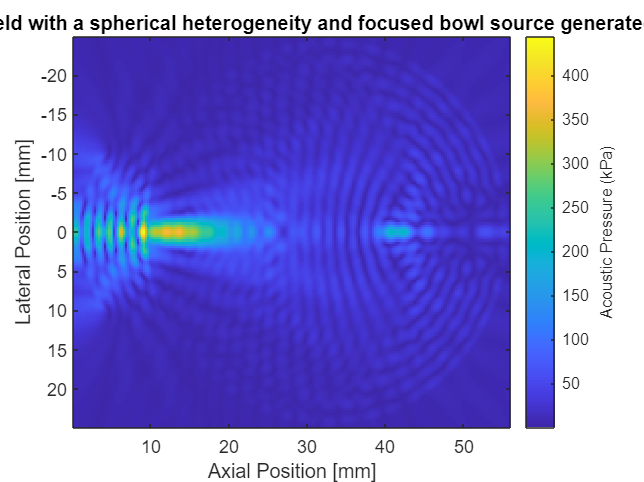


% plot the pressure field 
figure;
imagesc(1e3 * x_vecc, 1e3 * y_vec, 1e-3*amp.');
xlabel('Axial Position [mm]');
ylabel('Lateral Position [mm]');
axis image;
title('Acoustic Pressure Field with a spherical heterogeneity and focused bowl source generated using k-Wave');
a = colorbar;
a.Label.String = 'Acoustic Pressure (kPa)';

%caxis([0 160])

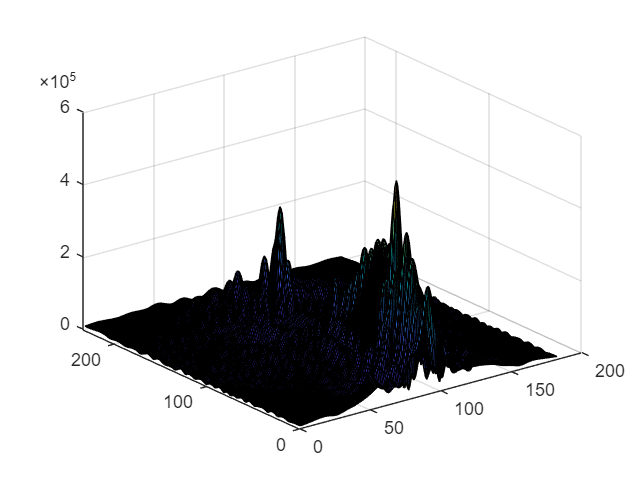

load('optimus2.mat','p_amp','p_phase')
y_vec = kgrid.y_vec - kgrid.y_vec(1);
y_vec = [-flip(y_vec(2:end)); y_vec];
optx = reshape(p_amp,234,183);
%optx = p_amp;
surf(optx)

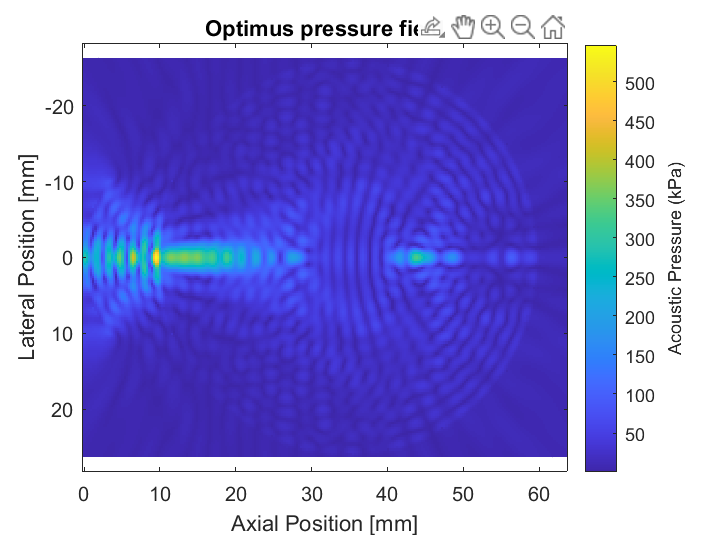

figure;
dxx = 2.727272727272727e-04;
%dxx = 5e-4;
optxx = optx(:,92);
%optxx = optx(:,93);
xarrayy = linspace(0,((234-1)*dxx),193);
%xarray = linspace(0,((234-1)*dxx),234);
xarray = linspace(-dxx/2,((234-0.5)*dxx),234);
yarray = linspace(((-96)*dxx),((96)*dxx),141);
imagesc(xarray*10^3,yarray*10^3,1e-3*optx');
ylabel('Lateral Position [mm]')
xlabel('Axial Position [mm]')
title('Optimus pressure field')
a = colorbar;
a.Label.String = 'Acoustic Pressure (kPa)';
%caxis([0 210])
axis equal

xarray(end)

ans = 0.0637

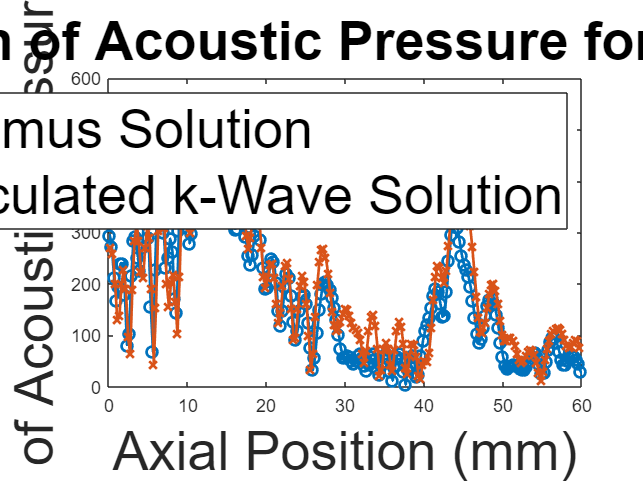

figure;
plot(xarray*10^3,optxx/10^3,'o','LineWidth',1.5,'LineStyle','-');
hold on 
plot((x_vec*10^3),FFTmag/10^3,'x','LineWidth',1.5,'LineStyle','-')

ylabel('Magnitude of Acoustic Pressure P(f) [kPa]','FontSize',30)
xlabel('Axial Position (mm)','FontSize',30)
title('Comparison of Acoustic Pressure for Simulation 7','FontSize',30)
set(gcs,'FontSize',30)
hold on
%load('benchmark.mat','p_amp','p_phase')
y_vec = kgrid.y_vec - kgrid.y_vec(1);
y_vec = [-flip(y_vec(2:end)); y_vec];
%optx = reshape(p_amp,234,183);
% optx1 = p_amp;
% %dxx = 2.727272727272727e-04;
% dxx = 5e-4;
% benchh = optx1(:,71);
% plot(xarray*10^3,benchh/10^3);
xlim([0 60])
legend('Optimus Solution','Calculated k-Wave Solution','FontSize',30);
hold off

surf(optx)

optxxx = optx(1:129,12:130)

optxxx = 	1.0e+05 *

    0.1127    0.1112    0.1072    0.1008    0.0920    0.0812    0.0687    0.0550    0.0406    0.0262    0.0125    0.0038    0.0134    0.0233    0.0316    0.0383    0.0438    0.0483    0.0525    0.0571    0.0629    0.0706    0.0807    0.0934    0.1087    0.1262    0.1455    0.1657    0.1858    0.2046    0.2209    0.2333    0.2406    0.2418    0.2359    0.2222    0.2006    0.1711    0.1341    0.0908    0.0430    0.0188    0.0683    0.1218    0.1730    0.2206    0.2654    0.3093    0.3511    0.3836
    0.1154    0.1174    0.1168    0.1137    0.1080    0.0998    0.0894    0.0772    0.0637    0.0494    0.0350    0.0211    0.0085    0.0059    0.0152    0.0236    0.0305    0.0359    0.0404    0.0445    0.0490    0.0548    0.0627    0.0734    0.0873    0.1044    0.1241    0.1458    0.1687    0.1915    0.2129    0.2315    0.2459    0.2545    0.2561    0.2496    0.2342    0.2094    0.1750    0.1315    0.0804    0.0315    0.0591    0.1249    0.1915    0.2504    0.2970    0.33

xarray(129)

ans = 0.0349

yarray(130)

ans = 0.0221

yarray(12)

ans = -0.0221

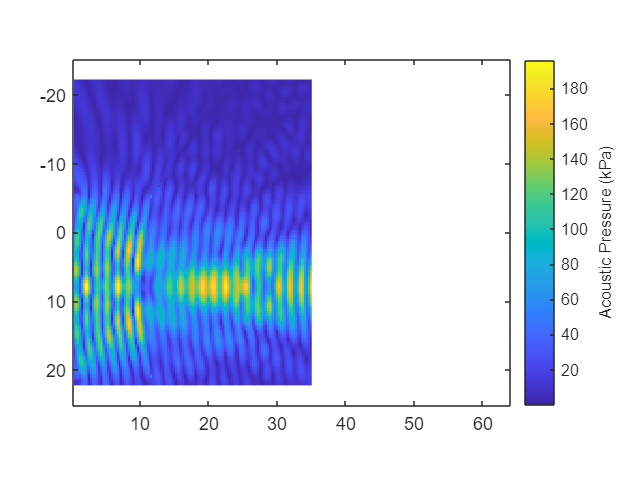

imagesc(xarray(1:129)*10^3,yarray(12:130)*10^3,1e-3*optxxx');
xlim([0.3 64])
axis equal;
%title('Acoustic Pressure Field with a heterogeneous medium of complex cranial geometry and focused bowl source generated using k-Wave');
a = colorbar;
a.Label.String = 'Acoustic Pressure (kPa)';

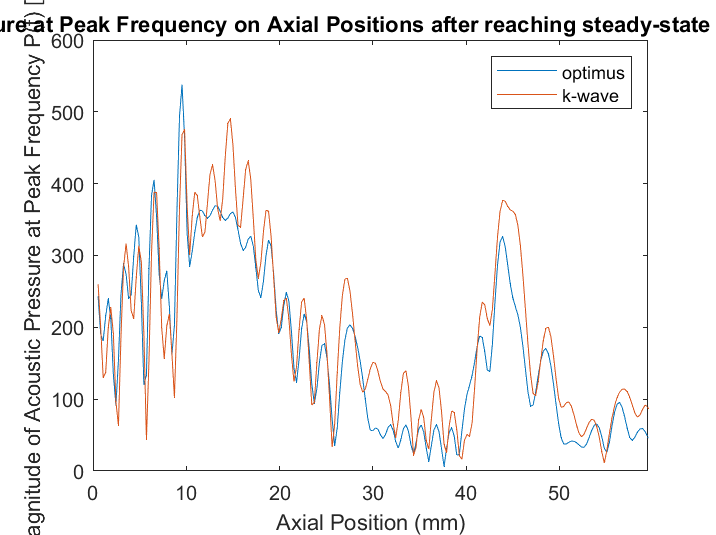


figure
vq2 = interp1(xarray,optxx,x_vec(2:end));
plot((x_vec(2:end)*10^3),vq2/10^3)
hold on 
plot((x_vec(2:end)*10^3),FFTmag(2:end)/10^3)
ylabel('Magnitude of Acoustic Pressure at Peak Frequency P(f) [kPa]')
xlabel('Axial Position (mm)')
title('Acoustic Pressure at Peak Frequency on Axial Positions after reaching steady-state with a bowl piston')
legend('optimus','k-wave')
xlim([0 59.5])
hold off

pctError = mean((abs(transpose(FFTmag(2:end))-vq2)./vq2)*100)

pctError = single
42.7425

D = (vq2-(transpose(FFTmag(2:end)))).^2;
S1= sum(D);
S2 = sum((vq2).^2);
ctest = 100*(sqrt(S1/S2))

ctest = single
25.9925

standarddev = std((abs(transpose(FFTmag(2:end))-vq2)./vq2)*100)

standarddev = single
50.7531

figure
pctError = (abs(transpose(FFTmag)-optxx(2:end))./optxx(2:end))*100;

Arrays have incompatible sizes for this operation.

Related documentation

%pctError = mean(100 * abs(FFTmag-vq2) ./ vq2);
plot((x_vec*10^3),pctError)

ylabel('Percentage error of acoustic pressure')
xlabel('Axial Position (mm)')
title('Acoustic Pressure at Peak Frequency on Axial Positions after reaching steady-state with a bowl piston')

xlim([0 59.5])
ppppp = pctError(1:50)
percentageerror = mean(ppppp)


figure
pctError = (abs(optxx(2:end)-transpose(FFTmag))./transpose(FFTmag))*100;
%pctError = mean(100 * abs(FFTmag-vq2) ./ vq2);
plot((x_vec*10^3),pctError)

ylabel('Percentage error of acoustic pressure')
xlabel('Axial Position (mm)')
title('Acoustic Pressure at Peak Frequency on Axial Positions after reaching steady-state with a bowl piston')

xlim([0 59.5])
percentageerror = mean(pctError(1:232))

timeperiod= 0:dt:t_end-dt;
periodofwave = 1/source_f0;
cyclelength = periodofwave/dt;
timeindex = Nt-(cyclelength-1);
wavetime = timeperiod(timeindex:Nt);
samplingfrequency = 1/dt;
freqv = (0:cyclelength/2-1)*samplingfrequency/cyclelength;
FFTarray = [];
FFTmag = [];
axialposition = axial_size/(Nx-1);
positionarray = [];
for i=1:(Nx-1)
    positionarray = [positionarray,axialposition*i];
    pressuretime = sensor_data.p(i, 1:Nt);
    cycleextract = pressuretime(timeindex:Nt);
    FFT = fft(cycleextract);

    %symmetric so remove second half
    FFT = FFT(1:(round(cyclelength,0))/2);
    
    %magnitude of fft
    mFFT = (abs(FFT));
    scaledFFT = mFFT*(2/PPP);
    [FFTpeak, FFTindex] = max(scaledFFT);
    peakfreq = freqv(FFTindex);
    FFTarray = [FFTarray,peakfreq];
    FFTmag = [FFTmag,FFTpeak];
end

figure;
plot(p_amp,p_phase)
figure;
plot(p_phase)
% plot(x_vec*10^3,FFTmag/10^3)
% ylabel('Magnitude of Acoustic Pressure at Peak Frequency P(f) [kPa]')
% xlabel('Axial Position (mm)')
% title('Acoustic Pressure at Peak Frequency on Axial Positions after reaching steady-state with a bowl piston')
% hold on
% plot()

spheree = [flip(medium.sound_speed,2),medium.sound_speed(:,2:end)];
spheree = rot90(spheree);
C = imfuse(spheree,amp.','blend')
figure;
% subplot(2,1,1);



imagesc(x_vec*1e3,y_vec*1e3,C);
axis equal
title('Acoustic Pressure field medium k-Wave')
xlabel('Axial Position [mm]');
ylabel('Lateral Position [mm]');
xlim ([0 63])
%colorbar
% subplot(2,1,2); 
% D = imfuse(spheree,optx.','blend')
% imagesc(x_vec*1e3,y_vec*1e3,D);
% axis equal
% title('Acoustic Pressure field medium OptimUS')
% xlabel('Axial Position [mm]');
% ylabel('Lateral Position [mm]');
% %colorbar
xlim ([0 63])


